% initial data
k1 = 1;
a01 = 0;
T1 = 0;
xi = 0;
k2 = 0.5;
a02 = 1;
T2 = 0.95;
T = 0.5;

A = [0 1; 0 -a02/T2];
B = [0; 1];
C = [k2*k1/T2 0];

Ad = zeros([2 2]);
Bd = zeros([2 1]);
for i = 0:5
    Ad = Ad + A^i*T^i/factorial(i);
    Bd = Bd + A^i*T^(i+1)/factorial(i+1)*B;
end

rank([Bd Ad*Bd])

ans = 2

rank([C; C*Ad])

ans = 2

Gd = [0 1; 0 0];
Hd = [1 0];

Mz = sylvester(-Ad',Gd,-C'*Hd);
L = (Hd*inv(Mz))'

L =     3.0224
    1.7055


Fz = Ad-L*C;
eig(Fz)

ans = 1.0e-08 *

   0.0000 + 0.7723i
   0.0000 - 0.7723i


P = sylvester(Ad, -Gd, Bd*Hd);
K = -Hd*inv(P)

K =    -5.1442   -2.6935


Freg = Ad+Bd*K;
eig(Freg)

ans = 1.0e-08 *

   -0.5759
    0.5759


x_initial = [1;0];
x_hat_initial = [0;0];
Tmdl = 5;

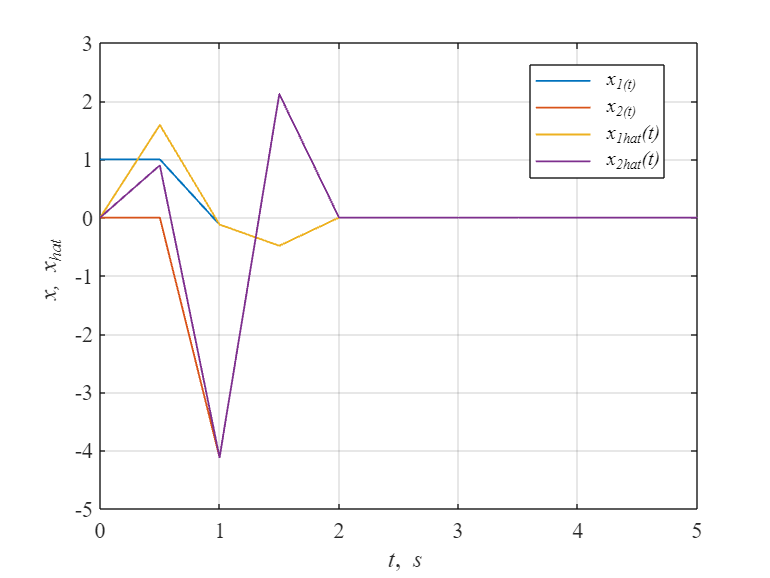

warning off
SimNew = sim("stab_model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
x = SimNew.out.signals(1).values;
x_hat = SimNew.out.signals(2).values;

x_tilde = x - x_hat;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x(:,1),'LineWidth',1)
hold on
grid on
plot(t,x(:,2),'LineWidth',1)
plot(t,x_hat(:,1),'LineWidth',1)
plot(t,x_hat(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x, x_{hat}')
legend('\it x_1(t)','\it x_2(t)','\it x_1_{hat}(t)','\it x_2_{hat}(t)','Location','best')

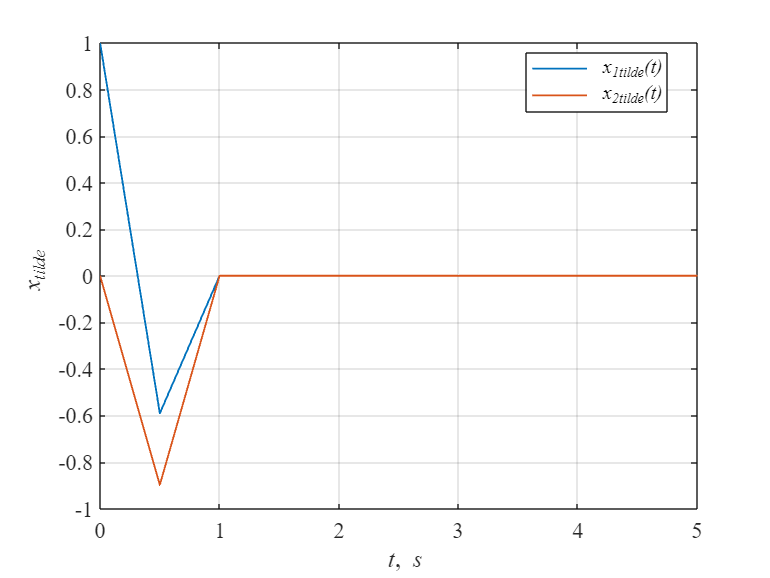

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x_tilde(:,1),'LineWidth',1)
hold on
grid on
plot(t,x_tilde(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x_{tilde}')
legend('\it x_1_{tilde}(t)','\it x_2_{tilde}(t)','Location','best')